liczba_probek = 20;
skok = 10;
err1 = compute_error(liczba_probek, skok, @generator_1);

solving ...
done


s = size(err1);
indexes = err1(2);
err1 = err1(:,1);
err2 = compute_error(liczba_probek, skok, @generator_2);

solving ...
done


err2 = err2(:,1);
err3 = compute_error(liczba_probek, skok, @generator_3);

solving ...
done


err3 = err3(:,1);
errors = [err1 err2 err3]

errors = 	1.0e+06 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0003
    0.0000    0.0000    0.0006
    0.0000    0.0000    0.0020
    0.0000    0.0000    0.0014
    0.0000    0.0000    0.0066
    0.0000    0.0000    0.0021
    0.0000    0.0000    0.0064
    0.0000    0.0000    0.0038
    0.0000    0.0000    0.0023


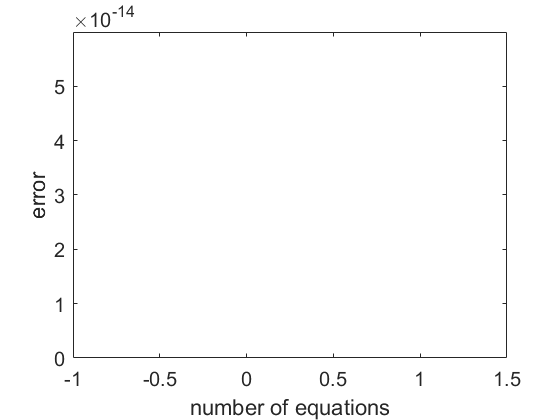

    plot(indexes, err1);
    xlabel('number of equations');
    ylabel('error');
    ax = gca;
    ax.FontSize = 15;